addpath 'C:\GitHub\CVUT-MatLab\BnB'
clear;clc;startup;yalmip('clear')

Toolbox "yalmip:R20230609:all" added to the Matlab path.

The MATLAB interface for Gurobi 10.0.3 has been installed.

The directory
    C:\Program Files\MATLAB\Gurobi\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


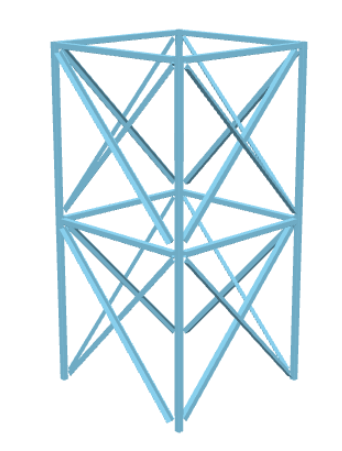

% nRhs = numel(table2array(Sections.RHS(:,"A")));
crossSectionsSet.import = importdata("sectionsSetRHS.mat");
crossSectionsSet.A = cat(1, table2array(crossSectionsSet.import(:,"A")));
crossSectionsSet.Iy = cat(1, table2array(crossSectionsSet.import(:,"I_y")));
crossSectionsSet.Iz = cat(1, table2array(crossSectionsSet.import(:,"I_z")));
crossSectionsSet.Ip = cat(1, table2array(crossSectionsSet.import(:,"I_t")));
na = numel(crossSectionsSet.A); 

## Ground structure

### Nodes

width = 2.9;
length = 2.9;
height = 3;
nbricks = 7;
topHeight = 20;
nodes.x = [[0;length;length;0];kron(ones(nbricks,1),[length/2;length;length/2;0;0;length;length;0])];                            % x coordinates of nodes
nodes.y = [[0;0;width;width];kron(ones(nbricks,1),[0;width/2;width;width/2;0;0;width;width])];                              % y coordinates of nodes
nodes.z = [0;0;0;0];
for i = 1:nbricks
    nodes.z  = [nodes.z; [height/2;height/2;height/2;height/2;height;height;height;height] + (i-1) .* [height;height;height;height;height;height;height;height]];
end
nodes.z((nbricks)*7+4:(nbricks+1)*7+4) =[topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight;topHeight;topHeight;topHeight]; % z coordinates of nodes
nnodes  = numel(nodes.x);                           % number of nodes

### Elements

modulNodes1 = [1;2;3;4; 1;5;2;5;2;6;3;6;3;7;4;7;4;8;1;8; 9;10;11;12  ];   % elements starting nodes
elements.nodes1 = (reshape(kron(modulNodes1', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(modulNodes1))*8);
modulNodes2 = [9;10;11;12; 5;10;5;9;6;11;6;10;7;12;7;11;8;9;8;12; 10;11;12;9  ];   % elements ending nodes
elements.nodes2 = (reshape(kron(modulNodes2', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(modulNodes2))*8);
nr = numel(elements.nodes1);  % number of elements 


modulElemGroup = [1;1;1;1; 3;3;3;3;3;3;3;3;3;3;3;3;3;3;3;3;    2;2;2;2];
pocetOpakovani = 4;
opakovani = repmat(modulElemGroup, 1, pocetOpakovani);
posuny = (0:pocetOpakovani-1) * 3;
elemGroup = opakovani + posuny;
elemGroup = [elemGroup(:, 1); elemGroup(:, 1); elemGroup(:, 2);  % První sloupec třikrát
          elemGroup(:, 2); elemGroup(:, 3); elemGroup(:, 3);  % Druhý sloupec třikrát
          elemGroup(:, end)];
ng = max(max(elemGroup));
Q = sparse(1:nr,elemGroup,1,nr,ng);
G = kron( Q, eye(na));

### Results

Plot the optimal design. Note that the dimensions are scaled.

SA_result = [7   ;  6  ;   6   ;  5   ;  9   ;  9  ;   5   ;  3  ;   9   ;  8   ;  8  ;   4];
SAvectorX = zeros(108,1);
for i = 1:12
    SAvectorX(SA_result(i)+(i-1)*na) = 1; 
end
[eigSA,volumeSA] = towerStabFn(SA_result,crossSectionsSet)

eigSA = 1.1324

volumeSA = 0.4722

BnB_result = [9   ;  2  ;   3   ;  7   ;  2   ;  3  ;   6   ;  1  ;   3   ;  2   ;  1  ;   3];
BnBvectorX = zeros(108,1);
for i = 1:12
    BnBvectorX(BnB_result(i)+(i-1)*na) = 1; 
end
[eigBnB,volumeBnB] = towerStabFn(BnB_result,crossSectionsSet)

eigBnB = 0.5834

volumeBnB = 0.2821

### Plotting SA

Plot the optimal design. Note that the dimensions are scaled.

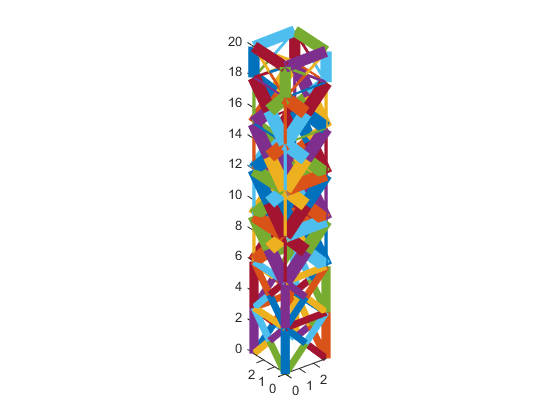

crossSectionsSA = reshape(G*SAvectorX, na, nr)'*crossSectionsSet.A;
crossSectionsBnB = reshape(G*BnBvectorX, na, nr)'*crossSectionsSet.A;
scale = max(max(value(crossSectionsSA)),max(value(crossSectionsBnB)));
nonzeroAreas = value(crossSectionsSA)>0;
p = plot3([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
          [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]',...
          [nodes.z(elements.nodes1(nonzeroAreas)) nodes.z(elements.nodes2(nonzeroAreas))]');
set(p, {'LineWidth'}, num2cell(10*value(crossSectionsSA(nonzeroAreas))/scale));
xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
axis equal

### Plotting BnB

Plot the optimal design. Note that the dimensions are scaled.

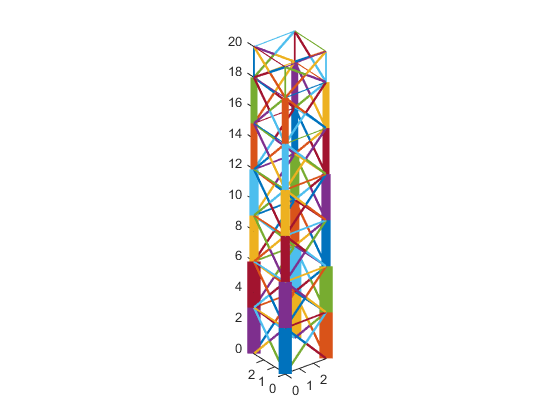

nonzeroAreas = value(crossSectionsBnB)>0;
p = plot3([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
          [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]',...
          [nodes.z(elements.nodes1(nonzeroAreas)) nodes.z(elements.nodes2(nonzeroAreas))]');
set(p, {'LineWidth'}, num2cell(10*value(crossSectionsBnB(nonzeroAreas))/scale));
xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
axis equal